# Q4. Object Detection *(20 points)*

## 0. Load Data and Add Path

###     0.1. Load data

load petGT.mat

###     0.2. Add the full path of 'petImages' folder

addpath(genpath("C:\Users\rarm1\Desktop\AI\week16_final"));

## 1. Sample Image (1)

Read the 33rd image in the table and display.

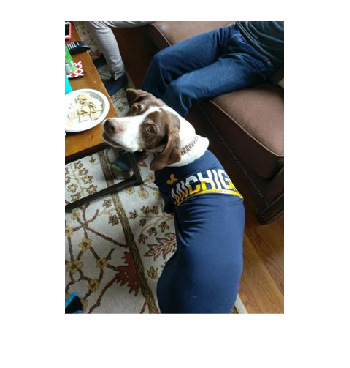

img_33rd = imread(petGT.imageFilename{33});
imshow(img_33rd)

## 2. Annotation (2)

Insert bounding box and label('Ginny') into the sample image, and display it as the figure in the right pane.

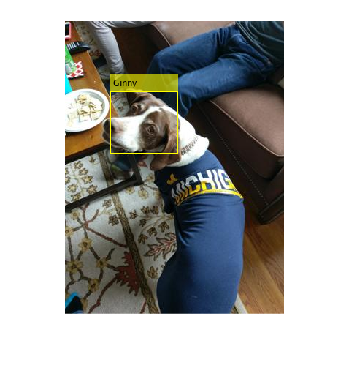

bbox_1 = petGT.Ginny{33};
label = petGT.Properties.VariableNames{2};
image_1 = insertObjectAnnotation(img_33rd,"rectangle",bbox_1,label);
imshow(image_1)

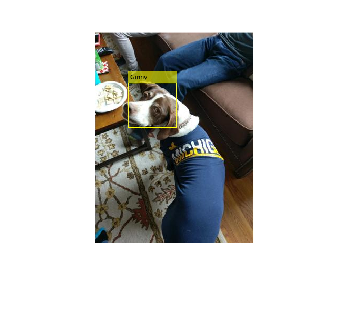

% 2. Figure
imshow(imread("Q4_answer1.jpg"))

## 3. Preprocessing Ground Truth (9)

Resize all images and their bounding boxes to 224 x 224 and display the scaled sample image.

###     3.1. Create datastores (2)

imageDS = imageDatastore(petGT.imageFilename);
bboxDS = boxLabelDatastore(petGT(:,2:end));

###     3.2. Combine datastores (1)

combineDS = combine(imageDS,bboxDS);

###     3.3. Resize datastores (1)

resizedDS = transform(combineDS,@scaleGT);

###     3.4. Read the resized data (5)

Read all images and display the scaled sample image as in the right pane.

- Tips: To display the 33rd image and its annotations, you need to read all the data in the datastore first. Use the MATLAB documentation.

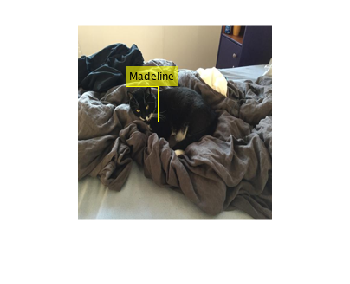

newGT = preview(resizedDS);

image_2 = insertObjectAnnotation(newGT{1},"rectangle",newGT{2},newGT{3});
imshow(image_2)

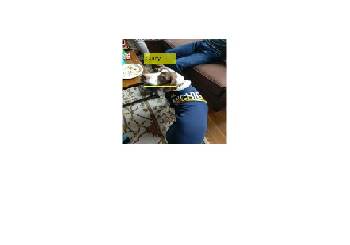

% 3.4. Figure
imshow(imread("Q4_answer2.jpg"))

Load a trained dectector. The detector detects pet faces.

load("detector.mat")

## 4. Object Detection (8)

###     4.1. Detect Objects (2)

      Use `detector` to detect a pet face in the sample image(the 33rd image in the datastore). Output the following three results.

- bounding box

- score

- label

[bboxes,scores,labels] = detect(detector,img_33rd);

###     4.2. Insert bounding boxes, labels and scores (3)

      Insert the bounding box, label, and score in the image as the figure in the right pane.

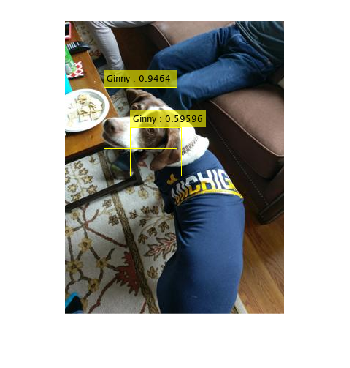

label_str = cell([height(labels) 1]);
for i = 1:height(labels)
    label_str{i} = [ char(labels(i)) ' : ' num2str(scores(i))];
end

image_3 = insertObjectAnnotation(img_33rd,"rectangle",bboxes,label_str);
imshow(image_3)

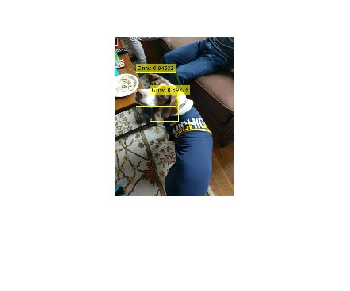

% 4.2. Figure
imshow(imread("Q4_answer3.jpg"))

###     4.3. Threshold detection (3)

     Apply a threshold the results to only include confident predictions. Extract detections above 90% confidence as the figure in the right pane.

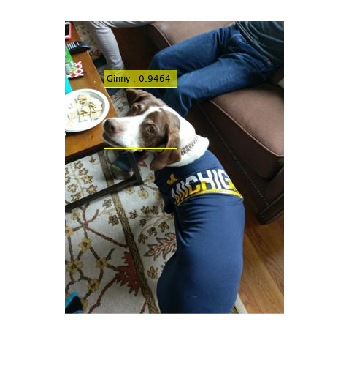

idx = scores > 0.9;

bboxes_threshold = bboxes(idx,:);
label_str_threshold = label_str(idx);

image_4 = insertObjectAnnotation(img_33rd,"rectangle",bboxes_threshold,label_str_threshold);
imshow(image_4)

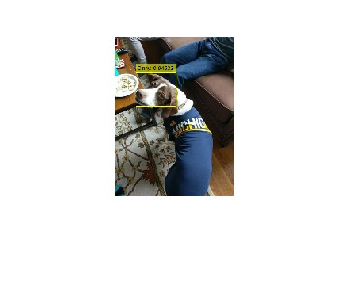

% 4.3. Figure
imshow(imread("Q4_answer4.jpg"))

### Support function

function data = scaleGT(data)  
    targetSize = [224 224];
    % data{1} is the image
    scale = targetSize./size(data{1},[1 2]);
    data{1} = imresize(data{1},targetSize);
    % data{2} is the bounding box
    data{2} = bboxresize(data{2},scale);
end